A=hilb(10);
x_true=[23 44 32 99 12 15 19 17 14 25]';
B_true=A*x_true;

B_perturb=B_true;
B_perturb=B_perturb+0.2;

x_lls=inv(A'*A)*(A*B_true);
x_perturb_lls=inv(A'*A)*(A*B_perturb);

error1=norm(x_true-x_lls)/norm(x_true);
error1=norm(x_true-x_perturb_lls)/norm(x_true);

**Plot**

plot(1:length(x_true),log10(x_true),'db','LineWidth',3)
xlabel('data indices')
ylabel('log of data values')
hold on
plot(1:length(x_true),log10(x_perturb_lls),'r','LineWidth',1)
hold off
legend('true data value','least square estimate')
set(gca,'Fontsize',12)
latex_fig(1,5,3)


eye(size(A,1))

**Tikhonov Regularisation**

lemda=linspace(0,0.5,50)

lemda =          0    0.0102    0.0204    0.0306    0.0408    0.0510    0.0612    0.0714    0.0816    0.0918    0.1020    0.1122    0.1224    0.1327    0.1429    0.1531    0.1633    0.1735    0.1837    0.1939    0.2041    0.2143    0.2245    0.2347    0.2449    0.2551    0.2653    0.2755    0.2857    0.2959    0.3061    0.3163    0.3265    0.3367    0.3469    0.3571    0.3673    0.3776    0.3878    0.3980    0.4082    0.4184    0.4286    0.4388    0.4490    0.4592    0.4694    0.4796    0.4898    0.5000


error_regu=zeros(1,50)

error_regu =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i=1:length(lemda)
    x_regu=(A'*A+lemda(i)*eye(size(A,1)))\(A*B_perturb);
    error_regu(i)=norm(x_true-x_regu)
end

error_regu =    1.0e+04 *

    4.6694         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081         0         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081         0         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081         0         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0082         0         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0082    0.0082         0         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0082    0.0082    0.0082         0         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0082    0.0082    0.0082    0.0082         0         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0082    0.0082    0.0082    0.0082    0.0082         0         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082         0         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082         0         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0083         0         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0083    0.0083         0         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0083    0.0083    0.0083         0         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0083    0.0083    0.0083    0.0083         0


error_regu =    1.0e+04 *

    4.6694    0.0070    0.0071    0.0071    0.0072    0.0072    0.0073    0.0073    0.0074    0.0074    0.0075    0.0075    0.0075    0.0076    0.0076    0.0077    0.0077    0.0077    0.0078    0.0078    0.0078    0.0078    0.0079    0.0079    0.0079    0.0079    0.0080    0.0080    0.0080    0.0080    0.0080    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0081    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0082    0.0083    0.0083    0.0083    0.0083    0.0083


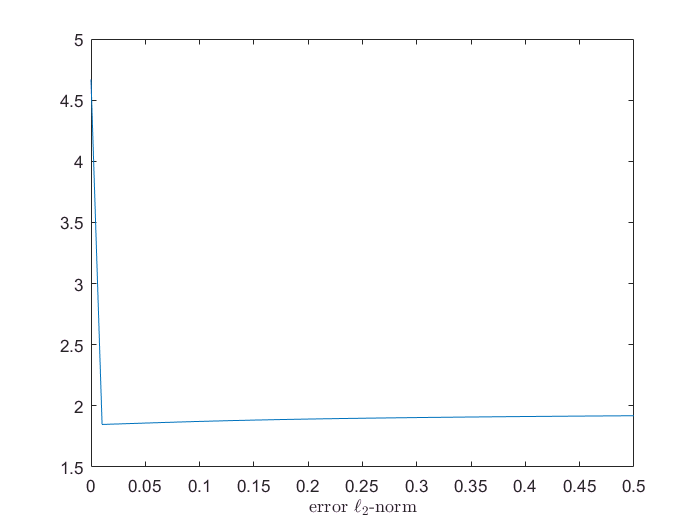

plot(lemda,log10(error_regu))
xlabel('regularization parameter $\lemda$','interpreter','latex')
xlabel('error $\ell_2$-norm','interpreter','latex')

%%Choosing lema l=0.0102
l=0.0102

l = 0.0102

x_regu=inv(A'*A+l*eye(size(A,1)))*(A*B_perturb)

x_regu =    28.9436
   41.3392
   39.3808
   35.9632
   32.7101
   29.8689
   27.4302
   25.3361
   23.5275
   21.9537


plot(1:length(x_true),log10(x_true),'db','LineWidth',3)
hold on
plot(1:length(x_true),log10(x_perturb_lls),'*r','LineWidth',3)

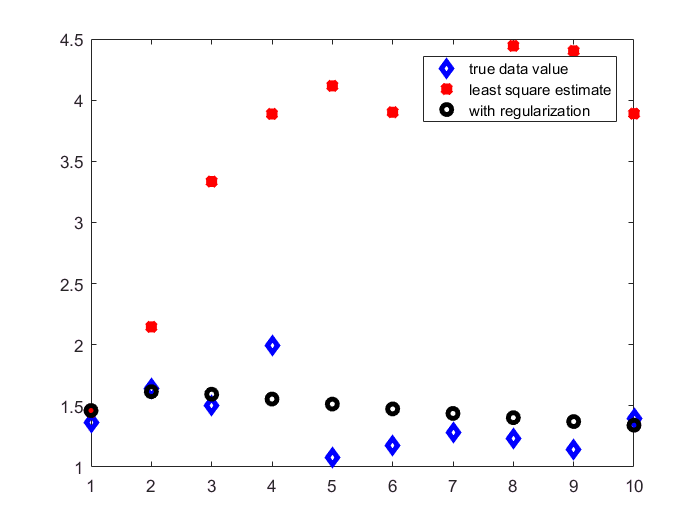

hold on
plot(1:length(x_true),log10(x_regu),'ok','LineWidth',3)
hold off
legend('true data value','least square estimate','with regularization')